# Exercises 7.1

2. Find an approximate solution for the BVP using weighted integrals with an approximate solution of the form u(x) =c1x3+c2x2+c3x+c4 and weight function sw1(x) = 1 and w2(x) =x.

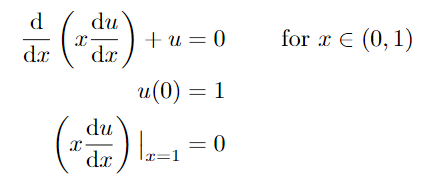

clear all
clc

syms c1 c2 c3 c4
syms x
u  = @(x) c1*x^3+c2*x^2+c3*x+c4;
w1 = @(x) 1;
w2 = @(x) x;
R  = @(x) diff(diff(u(x))*x) + u(x);
u0 = u(0) == 1

$$u0 = c_{4}=1$$

ux = diff(u(x))*x == 0;
ux1 = subs (ux, x, 1)

$$ux1 = 3\,c_{1}+2\,c_{2}+c_{3}=0$$

A1  = int(R(x)*w1(x), 0, 1) == 0

$$A1 = \frac{13\,c_{1}}{4}+\frac{7\,c_{2}}{3}+\frac{3\,c_{3}}{2}+c_{4}=0$$

A2  = int(R(x)*w2(x), 0, 1) == 0

$$A2 = \frac{49\,c_{1}}{20}+\frac{19\,c_{2}}{12}+\frac{5\,c_{3}}{6}+\frac{c_{4}}{2}=0$$

eqs = [subs(A1, c4, 1), ...
       subs(A2, c4, 1)];
A = solve ([eqs ux1], [c1 c2 c3]);
C1 = A.c1

$$C1 = -\frac{60}{17}$$

C2 = A.c2

$$C2 = \frac{138}{17}$$

C3 = A.c3

$$C3 = -\frac{96}{17}$$

C4 = 1

C4 = 1

u  = @(x) C1*x^3+C2*x^2+C3*x+C4;
R  = @(x) diff(diff(u(x))*x) + u(x);
ux = u(x)

$$ux = -\frac{60\,x^{3}}{17}+\frac{138\,x^{2}}{17}-\frac{96\,x}{17}+1$$

Rx = R(x)

$$Rx = \frac{180\,x}{17}-x\,\left(\frac{360\,x}{17}-\frac{276}{17}\right)-\frac{42\,x^{2}}{17}-\frac{60\,x^{3}}{17}-\frac{79}{17}$$

% clear all
% f = @(c1,c2,c3,c4) (13*c1)/4 + (7*c2)/3 + (3*c3)/2 + c4
% f(-60/17,138/17,-96/17,1)